# シンプルにGPRを実行するコード

mainAttiorbitで真値を作って，

学習（カーネル行列の計算）をmainGPで先に行ったら実行できるようになる．

clc
clear
close all

curdir = pwd;
addpath(genpath(strcat(curdir, '/../yoshimuLibrary/')));
addpath(genpath(strcat(curdir, '/../hara_functions/')));
addpath(strcat(curdir, '/../gpryui/'));

tStart = tic;

### input values directly

predictionStep = "ode" % "ode" or "simpleGP"

predictionStep = "ode"

shapes = ["freeMotion", "boxWing", "boxOneWing", "box"];
shapesUsed = ["boxWing"] % この検証で使う形状

shapesUsed = "boxWing"

validShape = "boxWing" % 真値の計算に使う形状

validShape = "boxWing"


tau = log(1);
sigma = log(0.25);
eta = log(0.1);
params = [tau, sigma, eta]; % hyper parameters

tstep = 1;
tstep_span = [0, tstep]; % for ode

% inputDim = 8; % [mApp, q, w]
outputDim = 7; % [mApp, delta_rvec, delta_w]

### read data

% read valid data -----
if strcmp(validShape, "flatplate")
    load('flatPlate.mat');
elseif strcmp(validShape, "boxWing")
    load('boxWing.mat'); % [sat, t_, jdHistory, r, v, q, phi, theta, psi, w, obsECI, obsRel, sunPosI]
end
y_valid = [mApp, q, w];

% read trained data -----
load('constGP.mat'); % [x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do, params]

### conditions for ode

TLE = 1;
lcModel = 'AS' % Ashikhmin-Shirley model

lcModel = 'AS'

const = orbitConst; % orbitConstの構造体に軌道運動の定数が定義されてる．
earthVSOP = vsopConst; % VSOP98の定数?
% satは読み込みdone
% orbit
if TLE == 1
    tle = readTLE('JCSAT2.txt', const); % yoshimuLibrary/examples/estimationLightCurve/
    % tle.oe(2) = 0.0001;
else
    a = 42164.91220781728; % [km]
    e = 0.000215800000000; % eccentricity
    inc = 0.000938987137573; % [rad]
    W = 4.918899828139163; % [rad]
    w = 0.876621287411436; % [rad]
    m = 1.585708419923936; % [rad]

    tle.oe = [a e inc W w m];
    tle.jd = 2.458535992836310e+06;
end
[rIni, vIni] = oe2rv(tle.oe, 1, const); % at inertial frame, km, km/s
rIni = rIni .* 10^3; % [m]
vIni = vIni .* 10^3; % [m/s]
jd = tle.jd; % Julian day, day

% attitude
qIni = q(1, :);
wIni = w(1, :);
% arrange
xIni = [rIni, vIni, qIni, wIni]; 

% observer location も読み込みdone
% obsECI: m, observer @ECI, [1, 3]

% 相対的な精度誤差（計算解の正しい桁数を制御），絶対許容誤差（計算解と真の解との差を制御）
options = odeset('RelTol', 1e-10, 'AbsTol', 1e-10); 

### ode と gprを回して逐次的に回帰

x_reg = zeros(size(t_, 1), 8); % preallocation [mApp, q, w] 回帰に使う入力
x_reg(1,:) = [mApp(1, 1), qIni, wIni]; % 初期値は真値

x_ode = zeros(size(t_, 1), size(xIni, 2));
x_ode(1,:) = xIni;

y_reg_mu = zeros(size(t_, 1), outputDim);
y_reg_var = zeros(size(y_reg_mu));
y_reg = zeros(size(y_reg_mu, 1), size(y_reg_mu, 2)); % (:, outputDim+1) rvをqにするから
y_reg(1,2:8) = [qIni, wIni];

for i = 1:1:size(t_, 1)-1

- gpr(観測ステップ)

    [y_reg_mu(i, 1), y_reg_var(i, 1)] = gprNormal(x_reg(i, 2:5), x_train(:, 2:5), y_train(:, 1), params, Kinv_Do); % input: [q_k], output: [mApp_k]
    y_reg_mu(i, 1) = y_reg_mu(i, 1) + y_train_mean(1, 1); % 回帰したmAppを平均0を戻して結果の変数に格納
    y_reg(i, 1) = y_reg_mu(i, 1);
    x_reg(i, 1) = y_reg_mu(i, 1);

- 1: ode（予測ステップ）input: x_ode, output: x (1 stepあとのodeに必要なx)

    if strcmp(predictionStep, "ode")
        [t, x] = ode45(@(t, x)eomCowellQ_h(t, x, const, earthVSOP, sat, jd), tstep_span, x_ode(i,:), options);
        x_ode(i+1,:) = x(end,:);
        x_reg(i+1,2:8) = x_ode(i+1, 7:13);
        y_reg(i+1, 2:8) = x_ode(i+1, 7:13);

- 2: gpr (予測ステップ)

    elseif strcmp(predictionStep, "simpleGP")
        for j = 2:1:size(y_reg_mu, 2)
            [y_reg_mu(i, j), y_reg_var(i, j)] = gprNormal(x_reg(i, :), x_train, y_train(:, j), params, Kinv_Dp); % 入力(:,8): mApp, q,w, 出力(:,7): mApp, delta_rv, delta_w
        end
        y_reg_mu(i, 2:end) = y_reg_mu(i, 2:end) + y_train_mean(1, 2:end); % 出力の平均を0にしたのを戻す
        % 回帰されたhat_delta_rvをqに戻して，姿勢計算をし，次の時刻の姿勢を求める．
        y_reg(i+1, 2:5) = qMult_h(y_reg(i, 2:5), rv2q(y_reg_mu(i, 2:4)));
        y_reg(i+1, 6:8) = y_reg(i, 6:8) + y_reg_mu(i, 5:7);
        % % モデル化誤差を考慮した姿勢をodeの次の入力のために格納
        % x_ode(i+1, 7:13) = y_reg(i+1, 2:8);
        % 次の回帰に使う入力を作成
        x_reg(i+1, :) = y_reg(i+1, :); % [mApp, q, w]
    end
end

- 最後にもう一回観測ステップをやって終わり

[y_reg_mu(end, 1), y_reg_var(end, 1)] = gprNormal(y_reg(end, 2:8), x_train(:, 2:8), y_train(:, 1), params, Kinv_Do); % input: [q_k], output: [mApp_k]
y_reg_mu(end, 1) = y_reg_mu(end, 1) + y_train_mean(1, 1); % 回帰したmAppの平均0を戻す
y_reg(end,1) = y_reg_mu(end,1);
x_reg(end,1) = y_reg_mu(end,1);

### export to csv

とりあえずしない

% 角速度をdegに変換
y_reg(:, 6:8) = rad2deg(y_reg(:, 6:8));
y_valid(:, 6:8) = rad2deg(y_valid(:,6:8));

### plot

mkdir ./results/GP/

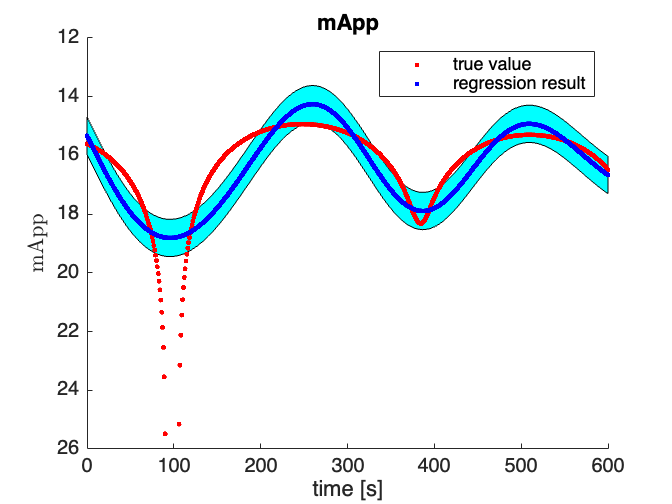

savedir = strcat(curdir, '/results/GP/');

fignames = ["mApp", "q1", "q2", "q3", "q4", "w1", "w2", "w3"];
x_label = "time [s]";
y_labels = ["mApp", "$q1$", "$q2$", "$q3$", "$q4$", "$\omega 1$ [deg/s]", "$\omega 2$ [deg/s]", "$\omega 3$ [deg/s]"];

figure('Name', fignames(1));
plot_gpr(t_(:,1), y_reg(:,1), y_valid(:,1), y_reg_var(:,1), fignames(1), x_label, y_labels(1), savedir, 1);

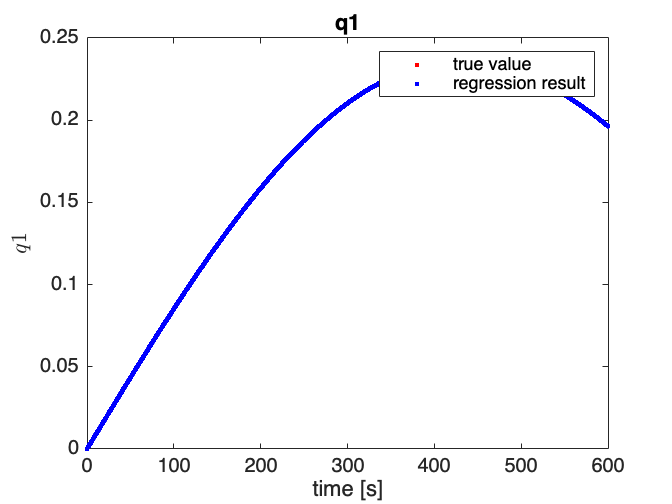

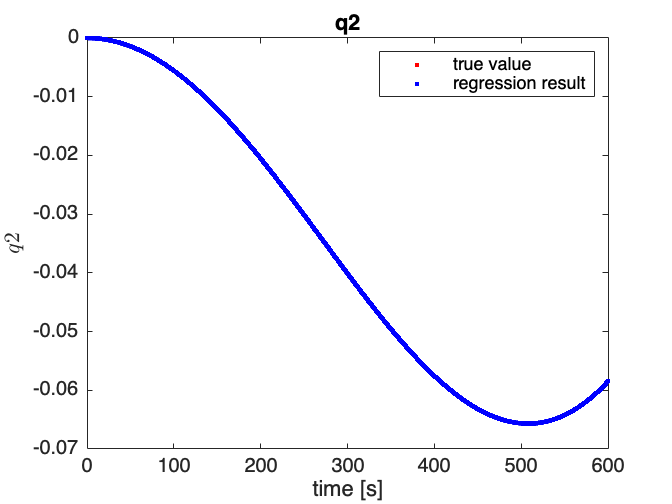

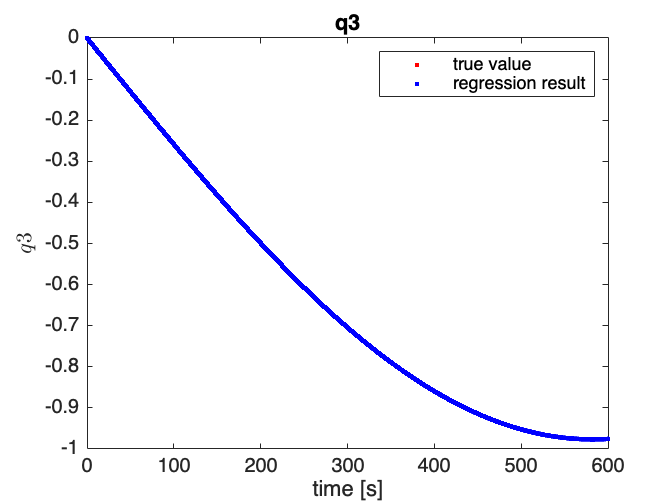

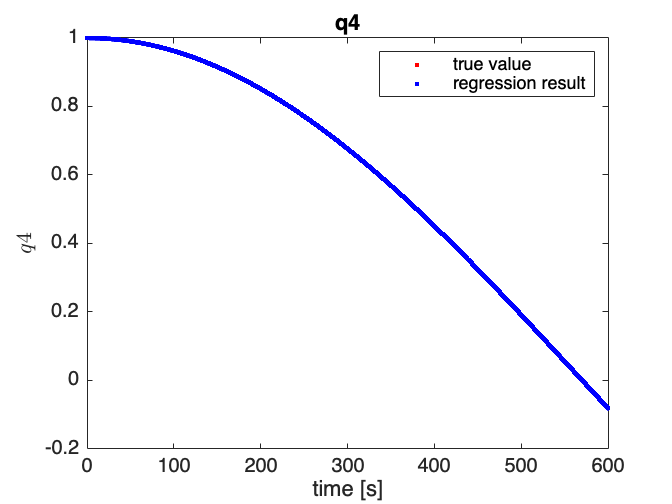

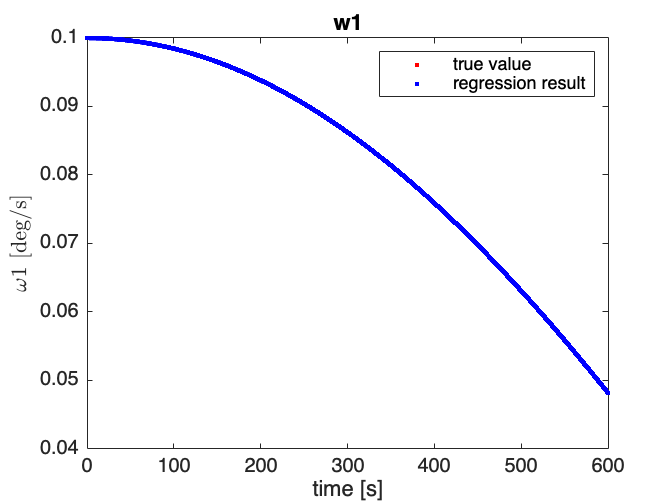

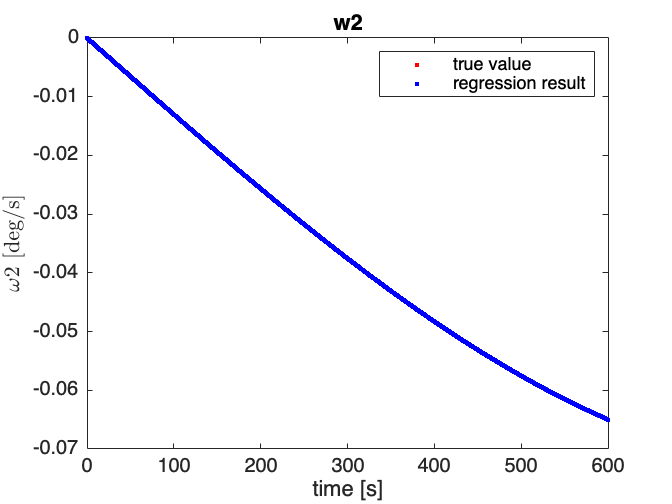

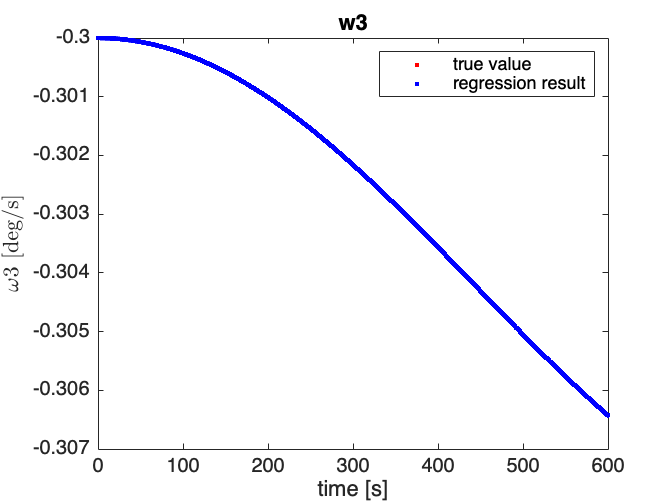


for i = 2:1:size(fignames, 2)
    figure('Name', fignames(i));
    plot_atti(t_(:, 1), y_reg(:, i), y_valid(:, i), fignames(i), x_label, y_labels(i), savedir)
end

% figure('Name', fignames(1));
% plot_gpr(t_(:,1), y_reg(:,1), y_valid(:,1), y_reg_var(:,1), fignames(1), x_label, y_labels(1), savedir, 1);

tEnd = toc(tStart);